clc; clf; clear;
n=4;N=2^n; 

t=2;
eps=1e-4;

P0 = zeros(N,N); P0(1,1)=1;
%P0 is Hermitian

temp=rand(N,N); 
XX = expm(1i*(temp+temp'));
X = XX*kron([1 0; 0 -1], eye(2^(n-1)))*XX';
%X is unitary and Hermitian

temp=rand(N,N); 
GG = expm(1i*(temp+temp'));
G = GG*kron([0 1; 1 0], eye(2^(n-1)))*GG';
%G is unitary and Hermitian Gamma

Q= X'*P0*X;           %Q
M = X'*P0*G*P0*X;     %M
W = X'*P0*G*X;        %W


T1= eye(N) + (cos(t)-1)*Q + eps*(cos(t)-1)*(W+W') + eps*(2-2*cos(t)-t*sin(t))*M;
T2= eye(N) + (cos(t)-1)*Q + eps*(cos(t)-1)*(W+W') + eps*(2-2*cos(t)-t*sin(t))*M;
S1= sin(t)*Q + eps*sin(t)*W + eps*( t*cos(t)-sin(t))*M;
S2= sin(t)*Q + eps*sin(t)*W' + eps*( t*cos(t)-sin(t))*M;
%% TERM for Oli_expression

state= eye(N);
oli_expression = trace(P0*T1*state*T2)+ trace(S1*state*S2)-trace(P0*state)

oli_expression = 0.8192

% The expression is always positive for maximally mixed state

A = kron([0 0; 1 0],(P0+eps*G)*X);
U = expm(1i*(A+A')*t);

state = eye(N);
sigma= U* kron([1 0; 0 0],state)*U';
proj0_state= kron([1 0],eye(N))*sigma*kron([1 0]',eye(N));
proj1_state= kron([0 1],eye(N))*sigma*kron([0 1]',eye(N));
new_state = proj0_state+ proj1_state;

trace(P0*(new_state-state))

ans = 0.8192

oli_expression = trace(P0*T1*state*T2)+ trace(S1*state*S2)-trace(P0*state)

oli_expression = 0.8192

state = eye(N);
oli_sols = zeros(1000,1);
exact_sols= zeros(1000,1);
for j=1:1000
    sigma= U* kron([1 0; 0 0],state)*U';
    proj0_state= kron([1 0],eye(N))*sigma*kron([1 0]',eye(N));
    proj1_state= kron([0 1],eye(N))*sigma*kron([0 1]',eye(N));
    new_state = proj0_state+ proj1_state;
    
    exact_sols(j)= trace(P0*(new_state-state));
    oli_sols(j) = trace(P0*T1*state*T2)+ trace(S1*state*S2)-trace(P0*state);
    state = new_state;
end



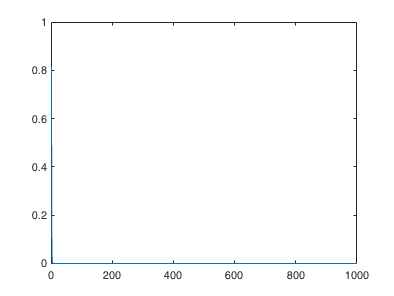

plot(real(exact_sols))